Author:** Michal Szabo**

Date:** 14.11.2021**

# Lab. 2 - Discrete optimization

## Exercise 1 - Knapsack problem with constraints

An airline cargo company has an airplane that flies from the UK to Spain on a daily basis to transport some cargo. Before the flight, it receives bids for deliveries from (many) customers. Each bid contains the weight of the cargo item to be delivered, the amount costumers are willing to pay and some other observations. The airline is constrained by the total amount of weight the plane is allowed to carry. The company must choose a subset of the packages (bids) to carry on the plane in order to maximize the total profit, taking into account the weight limit that they must respect and all other constraints. 

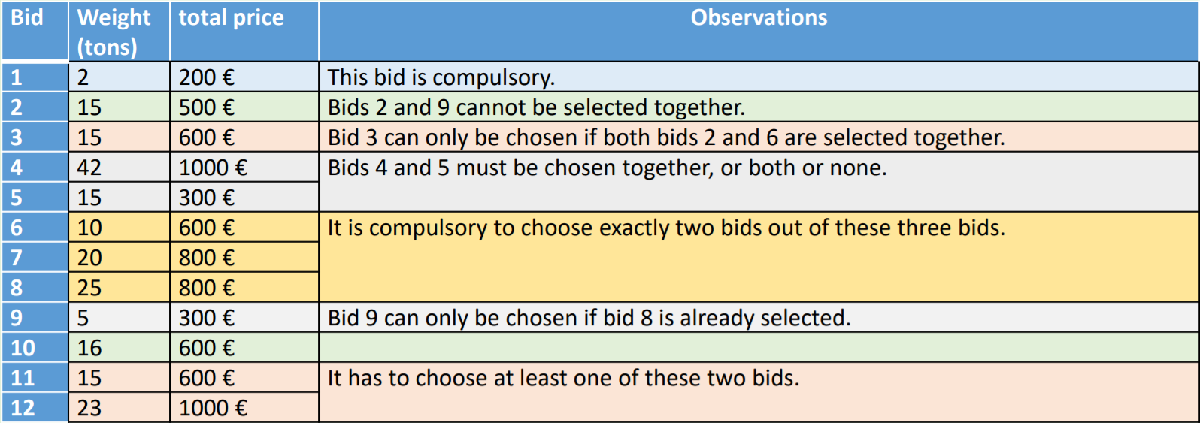

**Solution:**

(To see the slution better, click on it)

close all; clc; clear

w=[2 15 15 42 15 10 20 25 5 16 15 23]; % weights
v=[200 500 600 1000 300 600 800 800 300 600 600 1000]; % values
W=100; % capacity

A=[ w                                    % constraint 1
    0  1  0  0  0  0  0  0  1  0  0  0;  % constraint 3
    0 -1  2  0  0 -1  0  0  0  0  0  0;  % constraint 4
    0  0  0  0  0  0  0 -1  1  0  0  0;  % constraint 7
    0  0  0  0  0  0  0  0  0  0 -1 -1]; % constraint 8
   
%   1  3  4  7  8  
b= [W  1  0  0 -1];

Aeq=[ 1  0  0  0  0  0  0  0  0  0  0  0;  % constraint 2
      0  0  0  1 -1  0  0  0  0  0  0  0;  % constraint 5
      0  0  0  0  0  1  1  1  0  0  0  0]; % constraint 6

%     2  5  6
beq=[ 1  0  2];
lb=zeros(1,12);ub=ones(1,12);
opts = optimoptions('intlinprog','display','none');
[sol, val]=intlinprog(-v,1:12,A,b,Aeq,beq,lb,ub,[],opts);

solution = round([sol';w],0)

solution =      1     1     1     0     0     1     1     0     0     0     1     1
     2    15    15    42    15    10    20    25     5    16    15    23


backpack_weight = sum(sol.*w')

backpack_weight = 100.0000

backpack_value = -val

backpack_value = 4300

## Exercise 2 - Minimum cost flow 

Solve the following instance of the minimum cost flow, that is, calculate the flow at each of the 20 directed edges to supply goods from supply nodes 1 and 3 to demand nodes 2 and 4 satisfying the capacity constraints and that minimize the total cost.

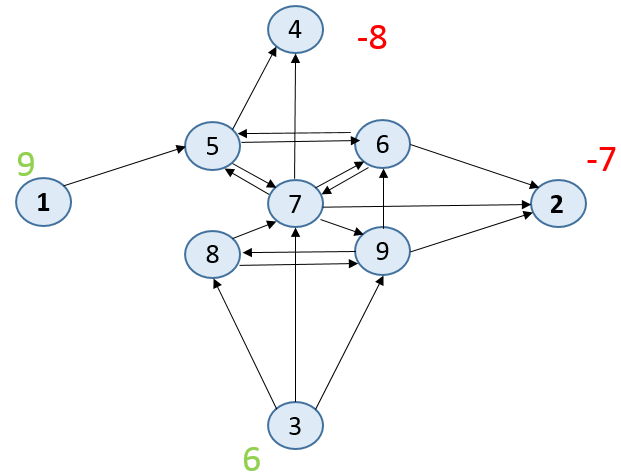

**Solution:**

clear

n=9;  % # nodes
m=20; % # edges

%     1  2  3  4  5  6  7  8  9 10 11 12 13 14 15 16 17 18 19 20
S=  [ 1  3  3  3  5  5  5  6  6  6  7  7  7  7  7  8  8  9  9  9]; % starting node
E=  [ 5  7  8  9  4  6  7  2  5  7  2  4  5  6  9  7  9  2  6  8]; % ending node
C=  [ 3  6  4  5  9  5  4  6  6  4  5  4  7  3  5  5  3  5  2  5]; % cost
W=  [ 9  4  3  2  4  2  5  4  5  4  5  4  5  2  4  5  4  3  5  3]; % capacity

Aeq=[ 1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0; %constraint for node 1
      0  0  0  0  0  0  0 -1  0  0 -1  0  0  0  0  0  0 -1  0  0; %constraint for node 2
      0  1  1  1  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0  0; %constraint for node 3
      0  0  0  0 -1  0  0  0  0  0  0 -1  0  0  0  0  0  0  0  0; %constraint for node 4
     -1  0  0  0  1  1  1  0 -1  0  0  0 -1  0  0  0  0  0  0  0; %constraint for node 5
      0  0  0  0  0 -1  0  1  1  1  0  0  0 -1  0  0  0  0 -1  0; %constraint for node 6
      0 -1  0  0  0  0 -1  0  0 -1  1  1  1  1  1 -1  0  0  0  0; %constraint for node 7
      0  0 -1  0  0  0  0  0  0  0  0  0  0  0  0  1  1  0  0 -1; %constraint for node 8
      0  0  0 -1  0  0  0  0  0  0  0  0  0  0 -1  0 -1  1  1  1];%constraint for node 9

    % 1  2  3  4  5  6  7  8  9 node
beq=[ 9 -7  6 -8  0  0  0  0  0]'; % supplies and demands
lb=zeros(20,1);
ub=W;
options = optimoptions('linprog','Display','off');
[xmin, fval, flag]=linprog(C,[],[],Aeq,beq,lb,ub,[],options);

from_to_flow = [S;E;xmin']

from_to_flow =      1     3     3     3     5     5     5     6     6     6     7     7     7     7     7     8     8     9     9     9
     5     7     8     9     4     6     7     2     5     7     2     4     5     6     9     7     9     2     6     8
     9     4     0     2     4     0     5     0     0     0     5     4     0     0     0     0     0     2     0     0


cost_capacity = [C;W]

cost_capacity =      3     6     4     5     9     5     4     6     6     4     5     4     7     3     5     5     3     5     2     5
     9     4     3     2     4     2     5     4     5     4     5     4     5     2     4     5     4     3     5     3


Cost_flow = fval

Cost_flow = 168

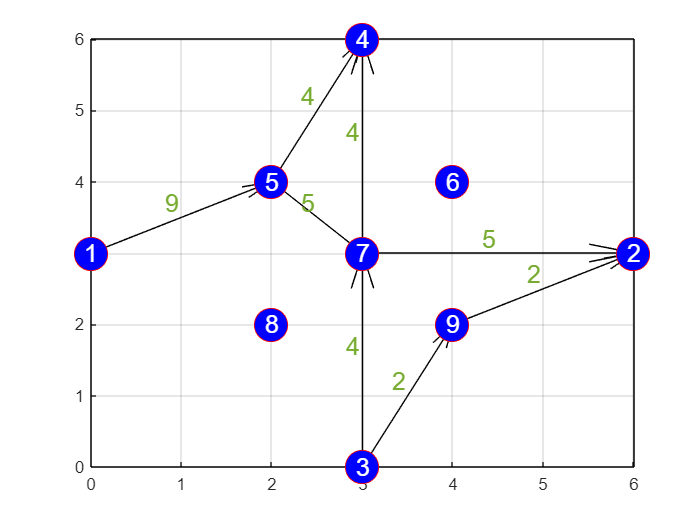

from_to = [S;E];
from_to = from_to.*(xmin~=0)';
from_to = from_to(from_to~=0);
from_to = reshape(from_to,2,length(from_to)/2);
S = from_to(1,:);
E = from_to(2,:);
flow = xmin(xmin~=0);

x = [0 6 3 3 2 4 3 2 4];
y = [3 3 0 6 4 4 3 2 2];

figure
hold on
rectangle('Position',[0 0 6 6])
for i=1:length(S)
    p1 = [x(S(i)) y(S(i))];      % First Point
    p2 = [x(E(i)) y(E(i))];      % Second Point
    dp = p2-p1;                  % Difference
    quiver(p1(1),p1(2),dp(1),dp(2), ...
        'AutoScale','on', ...
        'AutoScaleFactor',1, ...
        'MaxHeadSize',0.5, ...
        'Color','black')
    text(x(S(i))-0.1+dp(1)/2,y(S(i))+0.2+dp(2)/2,num2str(flow(i)),'Color','#77AC30','FontSize',15,'HorizontalAlignment','center')
end
for i=1:n
    plot(x(i),y(i),'o','MarkerSize',20,'Color','r','MarkerFaceColor','b')
    text(x(i),y(i),num2str(i),'Color','w','FontSize',15,'HorizontalAlignment','center')
end
grid on
hold off

## Exercise 3 - Traveling salesperson problem (TSP)

Use binary integer programming to solve the classic traveling salesman problem. This problem involves finding the shortest closed tour through a set of points. 

- a) Generate a set of 30 random points inside the square of opposite vertices (0,0) and (10,10)

- b) Considering $n^2$ binary variables $x_{\textrm{ij}}$, solve the following binary linear problem


$$\min \;\sum_{i=1}^n d_{\textrm{ij}} \cdot x_{\textrm{ij}}$$



$$\textrm{st}\;\sum_{i=1}^n x_{\textrm{ij}} =1$$
       
$$i=1\ldotp \ldotp \ldotp n$$



$$\textrm{st}\;\sum_{i=1}^n x_{\textrm{ij}} =1$$
      
$$j=1\ldotp \ldotp \ldotp n$$


- c) Add suitable integer variables and constraints to the previous problem to found the shortest closed tour passing through all points.

**Solution:**

(Sometimes it takes a lot of time to calculate optimal solution)

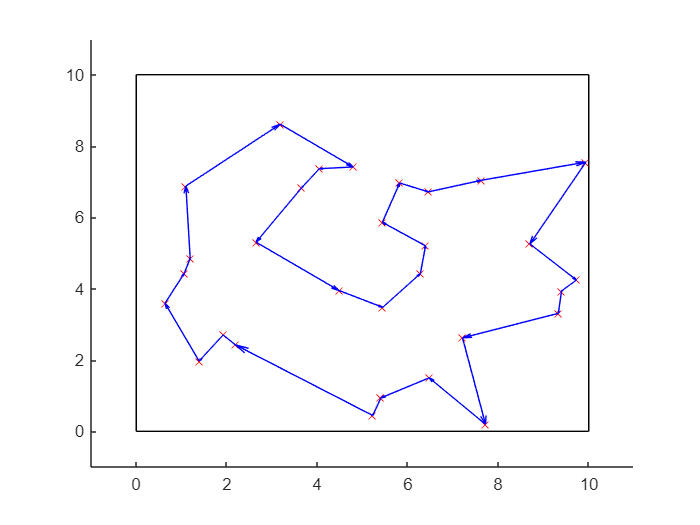

clear

n=30; % number of points
m = n*(n-1);
% P=zeros(n,2); % inicialize point's coordinates
D=zeros(n,n); % inicialize distance matrix
P=rand(n,2)*10; % generate n random points
figure
rectangle('Position',[0 0 10 10])
axis([-1 11 -1 11])
hold on
plot(P(:,1),P(:,2),'rx') % draw the points as red crosses
for i=1:(n-1) % calculate distance matrix
    for j=(i+1):n
        D(i,j)=norm(P(i,:)-P(j,:));
        D(j,i)=D(i,j);
    end
end

%         Calculates the vector f
% f= # of cities, D(i,j)=distance from city i to city j
% f must be a vector of 2·n·(n-1) coeficients associated to the variables
% x(1), x(2),...,x(n·(n-1)), y(1), y(2),...,y(n·(n-1))
% writes the distance matrix D in a one dimensional vector
f=reshape(D,1,n*n);
% deletes variables related with edges ii (size(f)=n*(n-1))
f=f(f~=0);
% add to the previous vector n·(n-1) coeficients associated to the y variables
f=[f,zeros(1,n*(n-1))];


% Equality constraints
o = ones(1,n-1);
z = zeros(1,n-1);
e = eye(n);

A1 = [];
for i=1:n
    r = [];
    for j=1:n
        if i==j
            r = [r,o];
        else
            r = [r,z];
        end
    end
    A1(i,:) = r;
end

A2 = [];
for i=1:n
    A2 = [A2,z];
    for j=1:n
        if i==n
            break
        end
        A2 = [A2,e(i,1:n-1)];
    end
end
A2 = reshape(A2',[],n)';

A3=A1-A2;
A4=-(n-1)*eye(m);
O = zeros(n,m);

% Final Aeq matrix
Aeq = [A1  O;
       A2  O;
        O A3];

% Final beq matrix
beq = [ones(2*n,1);n-1;-ones(n-1,1)];

% Inequality constraints
A = [A4, eye(m)];
b = zeros(m,1);

lb=zeros(2*m,1);
ub=[ones(m,1);100*ones(m,1)];
options = optimoptions('intlinprog','Display','off');
[x,fval]=intlinprog(f,1:(2*m),A,b,Aeq,beq,lb,ub,[],options);

dist = x.*f';
m1 = reshape(dist(1:m),[],n-1);         % Matrix with n-1 columns
m2 = [zeros(1,n-1); m1];                % Adding diagonal zeros
M = reshape([reshape(m2,[],1);0],[],n); % Reshaping final matrix and adding last diagonal zero

%% Plotting traveling lines

l = [];
for i=1:n
    l(i) = find(M(i,:));
end
for i=1:n
%     line([P(i,1),P(l(i),1)],[P(i,2),P(l(i),2)]) % Plotting lines
    % Plotting arrows
    p1 = [P(i,1) P(i,2)];            % First Point
    p2 = [P(l(i),1) P(l(i),2)];      % Second Point
    dp = p2-p1;                      % Difference
    quiver(p1(1),p1(2),dp(1),dp(2), ...
        'AutoScale','on', ...
        'AutoScaleFactor',1, ...
        'MaxHeadSize',0.3, ...
        'Color','b')
end
hold off

I found the best solution for traveling salesman problem without disjoint cycles. For this I needed to create aditional constraint for the cost flow.

## Exercise 4 - Scheduled services. Minimum spanning tree

We want to select a set of scheduled services among these previous 20 airports so that we can go from any airport to any other airport using some of these services (probably making more than one making transfer through other airports).

A scheduled service consists of a flight from one airport to another. Always the return service exists, that means, for instance, if we can go from San Francisco to Los Angeles, there exist also the service from Los Angeles to San Francisco. That is equivalent to consider the graph as an undirected graph. Which is the selection that minimize the sum of distances of all services? Solve the problem by implementing the Prim algorithm. 

Matrix of distances

clear

n=20;
%    1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20
D=[  0 144 114 105  31 109 135 132  85  79 158  20  73 162 127 190 156  58  87  71;
   144   0 144 181 147  76 195  73  64 114 220 135  71  18  39  60  37 101  62 146;
   114 144   0  49  86 169  51  78 130  42  76  94 114 154 105 151 125 137  94  46;
   105 181  49   0  73 189  31 124 152  67  52  88 135 195 146 197 169 147 123  40;
   31  147  86  73   0 128 104 119  97  57 126  17  82 164 122 184 151  80  85  40;
   109  76 169 189 128   0 212 126  38 128 238 112  54  92  95 137 110  51  77 148;
   135 195  51  31 104 212   0 129 174  85  26 118 157 206 157 201 176 173 141  67;
   132  73  78 124 119 126 129   0  92  65 153 115  84  80  35  73  47 118  55  98;
    85  64 130 152  97  38 174  92   0  90 200  82  17  82  66 120 89   36  39 112;
    79 114  42  67  57 128  85  65  90   0 111  59  73 128  80 137 106  95  57  33;
   158 220  76  52 126 238  26 153 200 111   0 141 183 231 182 224 201 198 167  91;
    20 135  94  88  17 112 118 115  82  59 141   0  67 153 114 177 142  63  75  52;
    73  71 114 135  82  54 157  84  17  73 183  67   0  90  64 123  89  35  28  95;
   162  18 154 195 164  92 206  80  82 128 231 153  90   0  49  47  35 119  79 161;
   127  39 105 146 122  95 157  35  66  80 182 114  64  49   0  62  28  99  40 113;
   190  60 151 197 184 137 201  73 120 137 224 177 123  47  62   0  34 156 102 170;
   156  37 125 169 151 110 176  47  89 106 201 142  89  35  28  34   0 123  68 139;
    58 101 137 147  80  51 173 118  36  95 198  63  35 119  99 156 123   0  63 106;
    87  62  94 123  85  77 141  55  39  57 167  75  28  79  40 102  68  63   0  85;
    71 146  46  40  40 148  67  98 112  33  91  52  95 161 113 170 139 106  85   0]

D =      0   144   114   105    31   109   135   132    85    79   158    20    73   162   127   190   156    58    87    71
   144     0   144   181   147    76   195    73    64   114   220   135    71    18    39    60    37   101    62   146
   114   144     0    49    86   169    51    78   130    42    76    94   114   154   105   151   125   137    94    46
   105   181    49     0    73   189    31   124   152    67    52    88   135   195   146   197   169   147   123    40
    31   147    86    73     0   128   104   119    97    57   126    17    82   164   122   184   151    80    85    40
   109    76   169   189   128     0   212   126    38   128   238   112    54    92    95   137   110    51    77   148
   135   195    51    31   104   212     0   129   174    85    26   118   157   206   157   201   176   173   141    67
   132    73    78   124   119   126   129     0    92    65   153   115    84    80    35    73    47   118    55    98
    85    64   130   152    

**Solution:**

% Prim algorithm
[~,n] = size(D);                   % The matrix is n by n, where n = # nodes.
intree = [1];  nintree=1;          % intree= nodes selected. nintree= #intree
k = 0;                             % k is the number of edges selected
notintree = [2:n]';nnotintree=n-1; % notintree= nodes not selected. nnotintree=#notintree 
 
cost = [];  % minimal cost
S = [];     % Starting node
E = [];     % Ending node
while nintree < n
% for p=1:5
  mincost = Inf;                            
  for i=1:nintree              
    for j=1:nnotintree
      ni = intree(i);
      nj = notintree(j);
      if D(ni,nj) < mincost 
        mincost = D(ni,nj);
        ei = ni;
        ej = nj;  % Save nodes and edge selected
      end
    end
  end
  S = [S, ei];  % Add starting node
  E = [E, ej];  % Add ending node
  cost = [cost D(ei,ej)];   % save minimal cost
  intree = [intree,ej];     % add node with minimal cost to memory
  nintree = nintree+1;      % explored nodes + 1
  notintree(notintree==ej) = [];    % removing node from unexplored
  nnotintree = nnotintree-1;    % unexplored nodes - 1
end

from_to = [S;E]

from_to =      1    12     5    20    20     4     7    10    10    19    13    13     9    19    15    17    15    17    14
    12     5    20    10     4     7    11     3    19    13     9    18     6    15    17    16     8    14     2


cost

cost =     20    17    40    33    40    31    26    42    57    28    17    35    38    40    28    34    35    35    18


final_cost = sum(cost)

final_cost = 614

## Exercise 5 - Optimal control. Dynamic programming

Let’s consider the system described by the dynamical model:


$$x_{k+1} =2x_k +u_k$$

$$\;\;\;\;\Longrightarrow \;\;$$

$$\;\;\;x_{k+1} =\mathit{\mathbf{a}}\cdot x_k +{\mathit{\mathbf{b}}\cdot u}_k$$
     

so   $\mathit{\mathbf{a}}=2,\;\mathit{\mathbf{b}}=1$

Considering an initial state ${\mathit{\mathbf{x}}}_0 =10$, obtain using a dynamic programming formulism the set of control signals 

$\textrm{uk},\;k=0,\ldotp \ldotp \ldotp ,9$ in a way that minimizes the cost function:


$$C=\sum_{k=0}^9 \left(2\cdot x_k^2 +u_k^2 \right)+2x_{10}^2 \;\;\;\;\;\;\Longrightarrow$$
    
$$C\left(x_k ,u_k \right)=\frac{1}{2}\sum_{k=1}^{10} \left(\mathit{\mathbf{q}}\cdot x_k^2 +{\mathit{\mathbf{r}}\cdot u}_k^2 \right)+\frac{1}{2}\cdot {\mathit{\mathbf{q}}}_{11} \cdot x_{11}^2 =\frac{1}{2}\sum_{k=1}^{10} \left(4x_k^2 +{2u}_k^2 \right)+\frac{4}{2}x_{11}^2$$


so      $\mathit{\mathbf{q}}=4,\mathit{\mathbf{r}}=2,{\mathit{\mathbf{q}}}_{11} =4$

Represent graphically the vectors $x_k$ and $u_k$ as a function of $k$.

**Dynamic model equations:**


$$p_{11} =q_{11}$$



$$p_k =q+a^2 p_{k+1} -a^2 b^2 p_{k+1}^2 \cdot {\left(r+b^2 p_{k+1} \right)}^{-1}$$



$$K_k ={\left(r+b^2 p_{k+1} \right)}^{-1} a\cdot b\cdot p_{k+1}$$



$$x_1 =10\;\;\;\;\;\;\;\;\;\;\;\;\;u_k =-K_k \cdot x_k$$



$$x_k =a\cdot x_{k-1} +b\cdot u_{k-1}$$


**Solution:**

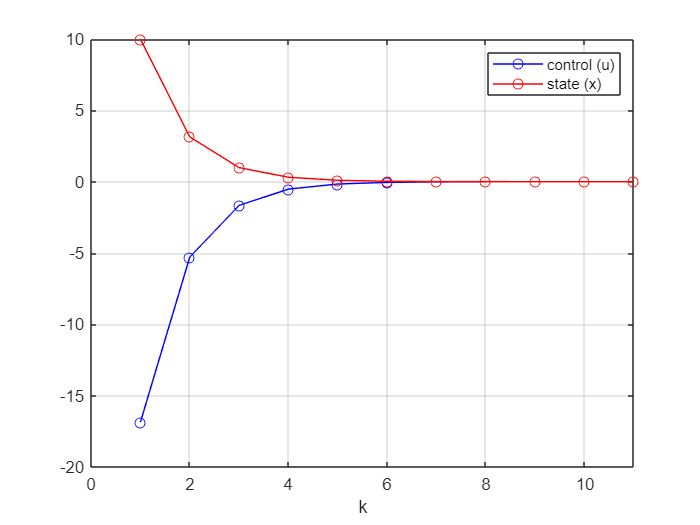

clear;

N = 11;
a = 2; b = 1;
q = 4; r = 2; qN = 4;
p = zeros(1,N); p(N)=qN;
K=zeros(1,N-1);
x=zeros(1,N-1); x(1)=10;
u=zeros(1,N-1);
for k=(N-1):-1:1
    p(k)=q+a^2*p(k+1)-a^2*b^2*p(k+1)^2*(r+b^2*p(k+1))^-1;
    K(k)=(r+b^2*p(k+1))^-1*a*b*p(k+1); 
end
for k=1:N-1
    u(k)=-K(k)*x(k);
    x(k+1)=a*x(k)+b*u(k);
end
figure
plot(1:(N-1),u,'o-b',1:N,x,'r-o')
legend('control (u)','state (x)')
xlabel('k')
grid on
xlim([0,N])

## Conclusion

Everything that I was doing is explained in the code and by comments. I tried to display the solution the best way I could so there was no cocnclusion or explanation needed for each of the exercises. I think I found all the optimal solutions.